**İÇİ DOLU DİKDÖRTGEN PRİZMA**

 v = [0 0 0;  % f'deki 1 noktası
      8 0 0;  % f'deki 2 noktası
      8 8 0;  % f'deki 3 noktası 
      0 8 0;];% f'deki 4 noktası
 
 %z ekseninin koordinatını değiştirerek tavanı da oluşturuyoruz ( 5 6 7 8 )
 v = [ v ;
       v+ [0 0 1] ];
 xlabel('x');
 ylabel('y');
 zlabel('z');
     
% hepsini tek tek çalıştırıp aşama aşama yaptık
 f = [1 2 3 4 ; % zemin
      5 6 7 8 ; % tavan
      1 5 6 2 ; 
      1 5 8 4 ;
      4 8 7 3 ;
      3 7 6 2 ]; 
 patch('Faces',f,"Vertices",v,'FaceColor','red')
 
 % zemin noktaları (0 0 0)-> 1,(8 0 0)-> 2,(8 8 0)-> 3,(0 8 0)-> 4
 % tavan noktaları (0 0 1)-> 5,(8 0 1)-> 6,(8 8 1)-> 7,(0 8 1)-> 8
 % (0 0 0) -> 1 ,(0 0 1) -> 5 ,(8 0 1) -> 6 ,(8 0 0) -> 2 noktalarını birleştirdik bu şekilde devam etti.
 
 %oluşturduğumuz dikdörtgen prizma şekline üçgen çatı ekleyelim
 v1 = [0 0 1;
       8 0 1;
       4 4 2;];
 
 v2 = [0 0 1;
       0 8 1;
       4 4 2;];
 
 v3 = [0 8 1;
       8 8 1;
       4 4 2;];
 
 v4 = [8 8 1;
       8 0 1;
       4 4 2;];
 
 f1 = [1 2 3]

f1 =      1     2     3


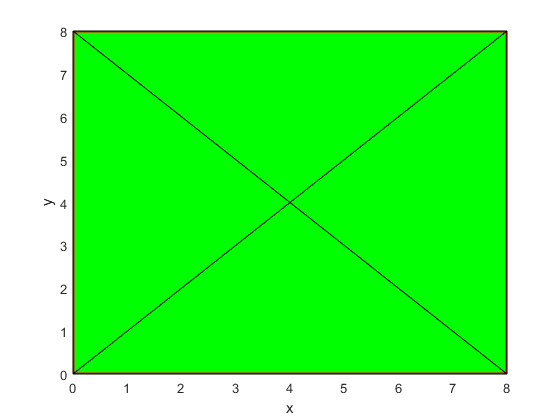

 
 
  patch('Faces',f1,"Vertices",v1,'FaceColor','green')
  patch('Faces',f1,"Vertices",v2,'FaceColor','green')
  patch('Faces',f1,"Vertices",v3,'FaceColor','green')
  patch('Faces',f1,"Vertices",v4,'FaceColor','green')